N=1500;
fs=1000;
dt=1/fs;
t=(0:N-1)*dt

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


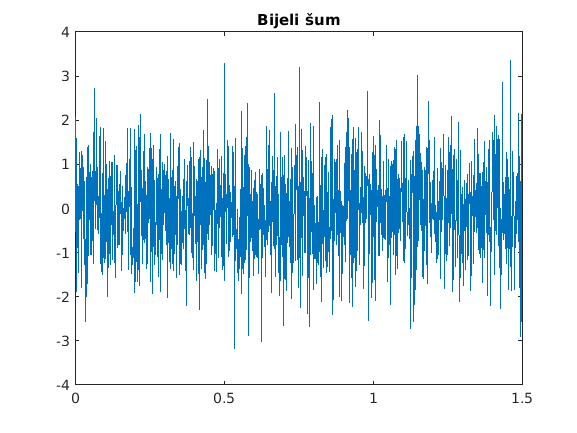

white_noise = randn([N 1])'; 
pink_noise = pinknoise([N 1])'; 

plot(t,white_noise);
title('Bijeli šum')

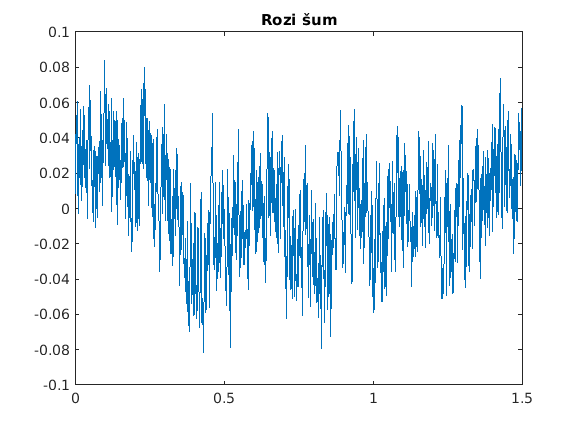

plot(t,pink_noise);
title('Rozi šum')

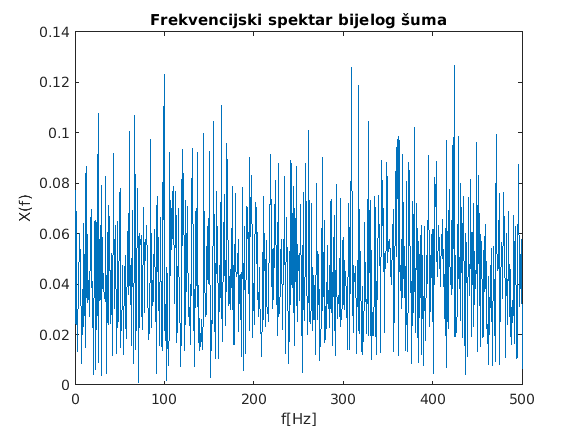


Y_pink=abs(fft(pink_noise));
Y_white=abs(fft(white_noise));

%white
P2 = Y_white/N;
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f_white = fs*(0:(N/2))/N;
plot(f_white,P1)
xlabel('f[Hz]')
ylabel('X(f)') 
title('Frekvencijski spektar bijelog šuma')

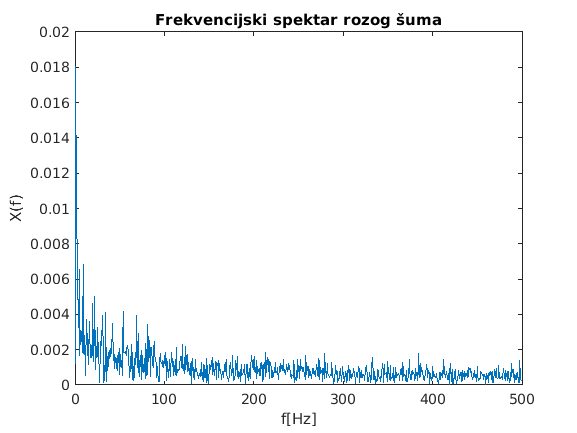


%pink 
P4 = Y_pink/N;
P3 = P4(1:N/2+1);
P3(2:end-1) = 2*P3(2:end-1);
f_pink= fs*(0:(N/2))/N;
plot(f_pink,P3)
xlabel('f[Hz]')
ylabel('X(f)') 
title('Frekvencijski spektar rozog šuma')

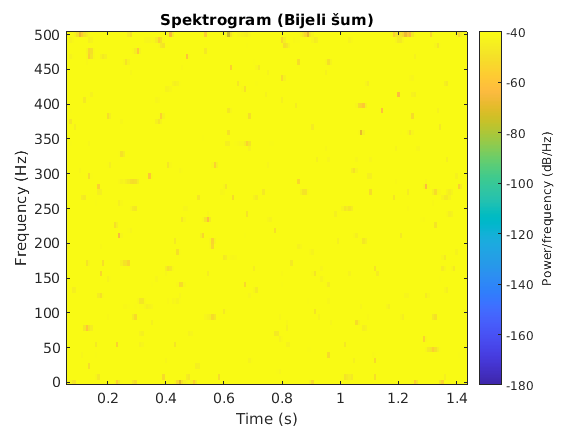


spectrogram(white_noise,128,120,128,1e3,'yaxis')
title('Spektrogram (Bijeli šum)')
caxis([-180 -40]);

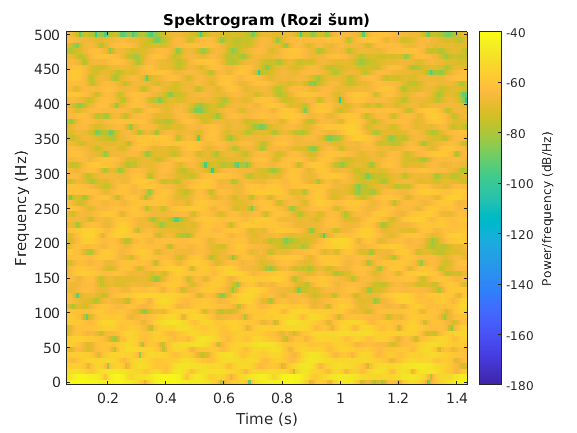

spectrogram(pink_noise,128,120,128,1e3,'yaxis')
title('Spektrogram (Rozi šum)')
caxis([-180 -40]);